imgarray_dark=loadRAWinArray_mono('D:\Luis\Documents\EIT_HS-Düsseldorf\Semester 6\EMVA1288_SimDataforVerification\Mono640x480_12bit_dsnu',640,480);
imgarray_50=loadRAWinArray_mono('D:\Luis\Documents\EIT_HS-Düsseldorf\Semester 6\EMVA1288_SimDataforVerification\Mono640x480_12bit_prnu',640,480);

images_dark=cellarray_to_3d_matrix(imgarray_dark);
images_50=cellarray_to_3d_matrix(imgarray_50);

imgarray_mv=loadRAWinArray_mono('D:\Luis\Documents\EIT_HS-Düsseldorf\Semester 6\EMVA1288_SimDataforVerification\Mono640x480_12bit_mv',640,480);

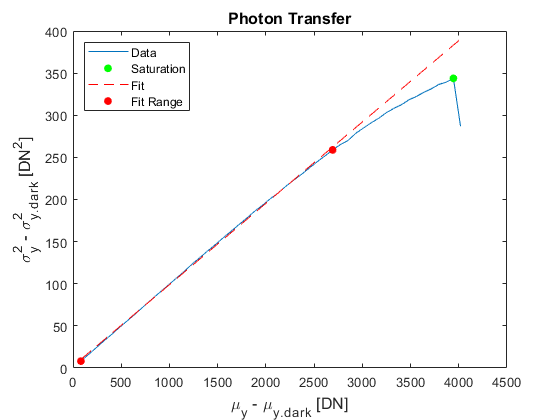

mean_dark = 29.4063

var_dark = 9.0780

K = 0.0966

[mean_dark,var_dark,K] = photonTransfer_curve_EMVA1288_mono(imgarray_mv)

temp_dark=compute_temporaldarknoise(var_dark,(1/12),K)

temp_dark = 31.0596

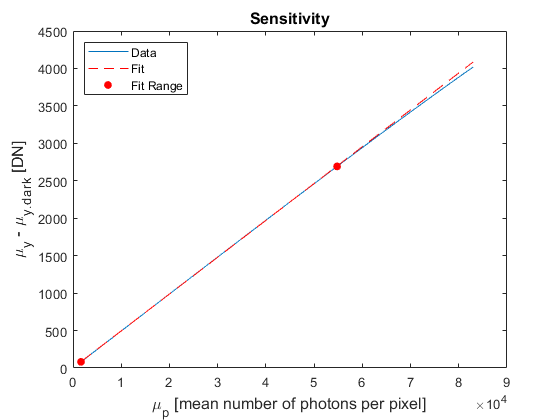

R = 0.0492

p_sat = 8.1323e+04

[R,p_sat] = sensitivity_curve_mono(imgarray_mv,1659.66)

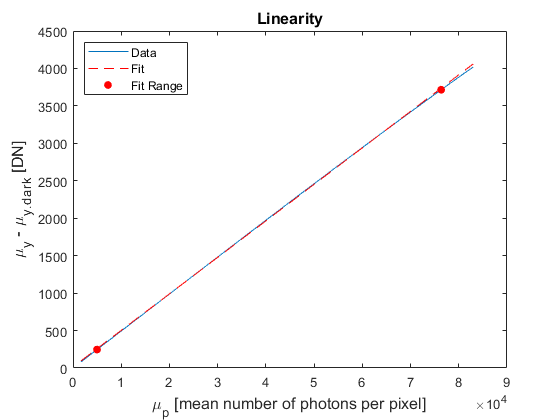

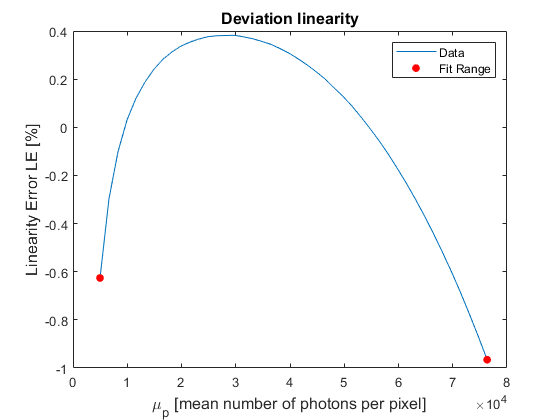

LE_min = -0.9656

LE_max = 0.3818

[LE_min,LE_max] = linearity(imgarray_mv,1659.66)

[DSNU,PRNU,sv_50,sv_dark,avg_img_dark,avg_img_50,var_stack_dark,var_stack_50] = DSNU_PRNU_3dmat(images_dark,images_50,K)

DSNU = 22.0316

PRNU = 0.9669

sv_50 = 395.9462

sv_dark = 4.5257

avg_img_dark =    30.8100   31.0100   29.7600   31.8200   30.4800   32.1100   28.6300   28.2800   29.0900   30.5200   32.1200   27.0800   26.4100   28.6600   26.7000   31.1200   30.3100   26.7400   28.8500   29.8500   30.9900   30.5400   28.8300   30.1400   28.3100   32.8900   31.3500   27.0300   29.8600   31.0200   32.5500   31.5000   27.6400   26.8200   29.7400   29.7200   30.4000   24.9000   27.4400   26.1700   30.3800   27.4200   28.4500   27.7500   28.7100   32.2100   30.5600   27.9500   28.8100   31.4100
   32.2200   27.5300   29.9800   29.0400   32.6600   29.6100   26.2700   26.8000   30.4600   31.2200   28.4700   29.7800   26.3000   24.8100   31.7300   27.8500   26.1600   25.2700   27.5400   31.4200   31.3500   28.4600   28.9000   30.1300   31.4600   31.1300   29.8700   29.6900   29.1500   33.4300   29.1100   25.5000   27.2000   29.4100   30.1300   26.4300   30.7300   25.5100   24.9800   29.4500   26.2900   26.4700   28.7900   31.2800   28.3200   30.5700   29.2400   26.2500   3

avg_img_50 = 	1.0e+03 *

    1.9971    2.0234    1.9997    2.0163    2.0288    2.0076    2.0156    2.0013    2.0108    1.9928    2.0142    2.0089    2.0113    2.0059    1.9960    2.0083    2.0018    2.0338    2.0128    1.9915    2.0238    2.0084    2.0005    2.0326    2.0145    2.0089    1.9929    2.0130    2.0255    2.0177    2.0362    2.0129    2.0137    2.0128    2.0059    2.0171    2.0303    2.0229    2.0043    2.0258    2.0183    2.0244    2.0177    2.0309    2.0306    2.0332    2.0234    2.0295    2.0197    2.0146
    2.0193    2.0185    2.0203    2.0129    2.0329    2.0025    2.0052    2.0197    2.0157    2.0168    2.0332    2.0217    2.0047    2.0130    2.0250    2.0091    2.0089    1.9922    2.0162    2.0022    2.0101    2.0131    2.0096    2.0188    2.0306    2.0151    1.9840    2.0243    2.0183    2.0272    2.0198    2.0072    2.0050    2.0215    2.0168    2.0193    2.0262    2.0362    2.0113    2.0161    2.0131    2.0265    2.0141    2.0280    2.0237    2.0311    2.0295    

var_stack_dark = 9.0819

var_stack_50 = 210.0982


p_min= absolute_sensitivity_threshold(R/K,var_dark,K)

p_min = 62.2267


e_sat = saturation_capacity(R/K,p_sat)

e_sat = 4.1432e+04

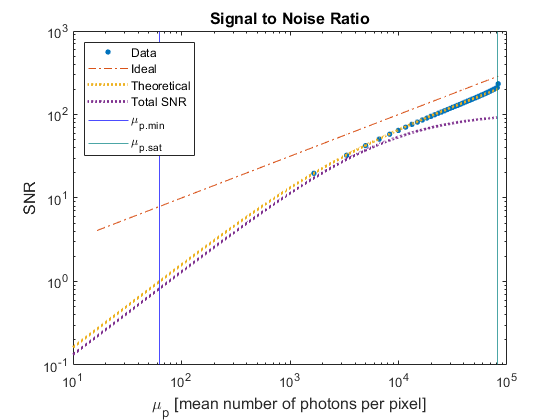

SNR_max = 203.5497

DR = 1.3069e+03

[SNR_max,DR] = plot_SNR(imgarray_mv,1659.66,p_min,p_sat,e_sat,temp_dark,1/12,K,R/K,DSNU,PRNU)

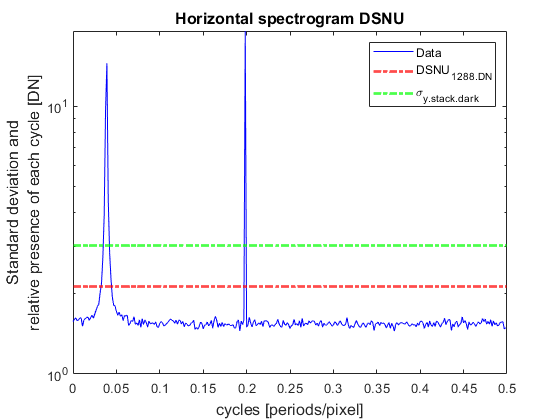

DSNU_var_white_dark = 2.3924

[DSNU_var_white_dark]=spectrogram(avg_img_dark,avg_img_50,'horizontal','DSNU',DSNU,var_stack_dark,K)

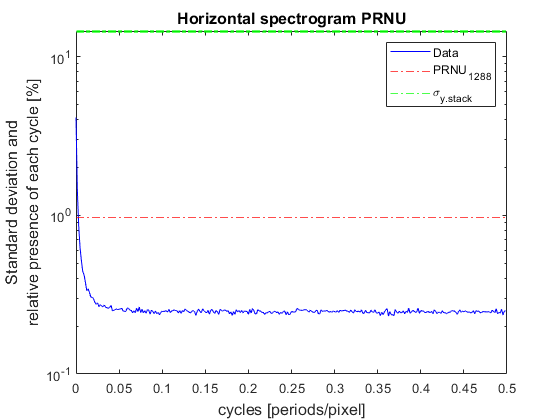

PRNU_var_white_dark = 125.8637

[PRNU_var_white_dark]=spectrogram(avg_img_dark,avg_img_50,'horizontal','PRNU',PRNU,var_stack_50,K)

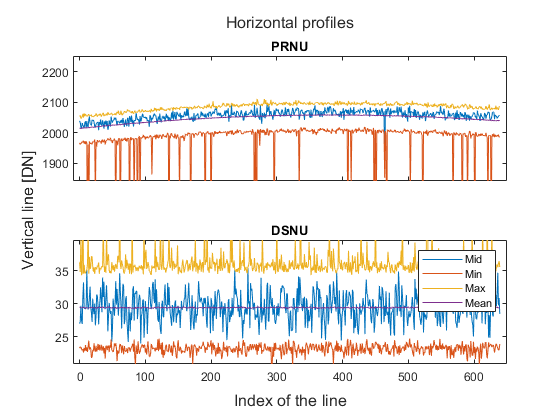

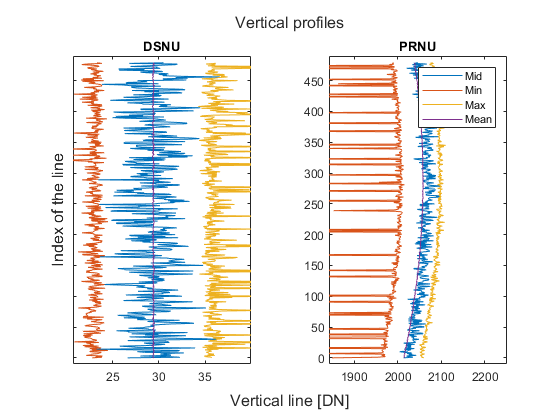

profiles(avg_img_dark,avg_img_50)

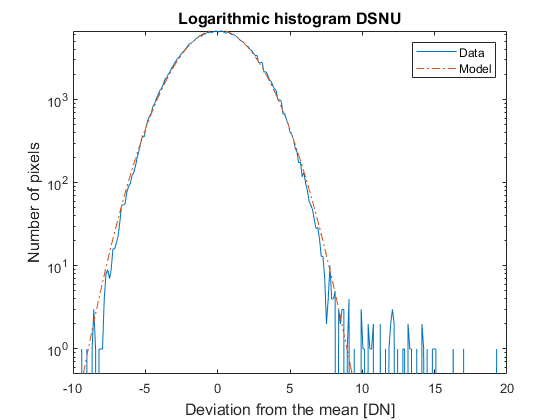

logarithmic_histogram_DSNU(avg_img_dark,100,sv_dark)

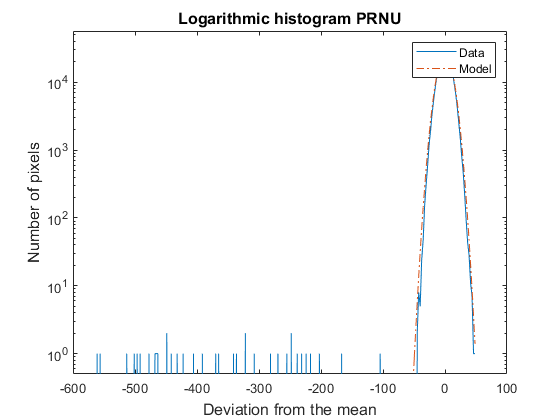

logarithmic_histogram_PRNU(avg_img_dark,avg_img_50,100)

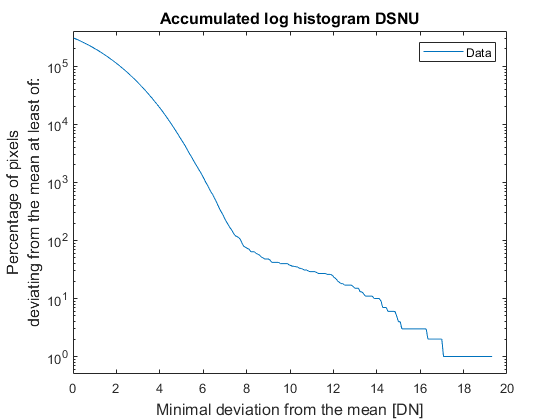

accumulated_log_histogram_DSNU(avg_img_dark,100)

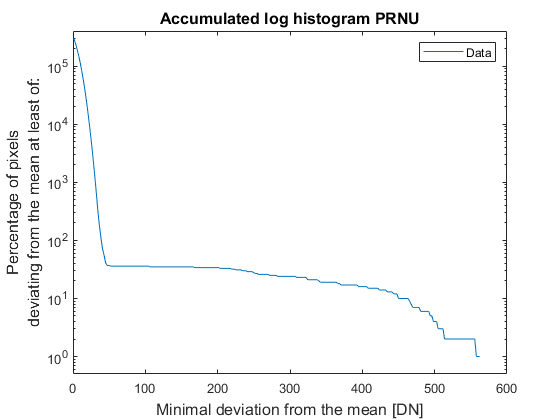

accumulated_log_histogram_PRNU(avg_img_dark,avg_img_50,100)